## The basic data

This is the first example in Lesson 1

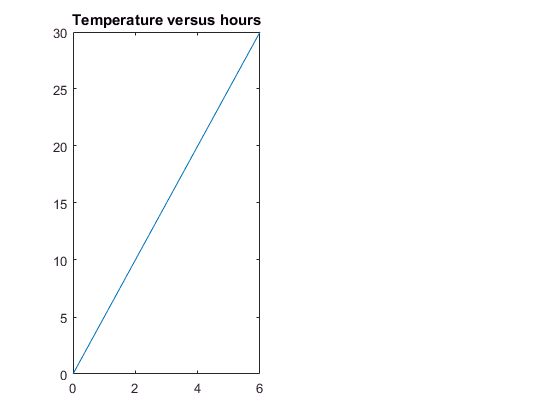

hours = 0:6;
temperature = 0:5:30;
plot(hours, temperature)
hold off
title('Temperature versus hours')

## Second step of the generalisation

We will show two plots: plot 1 is the same plot 'temperature' vs 'hours' as before (in blue) and plot 2 is the equation (in red):


$$$y = 5x$$$


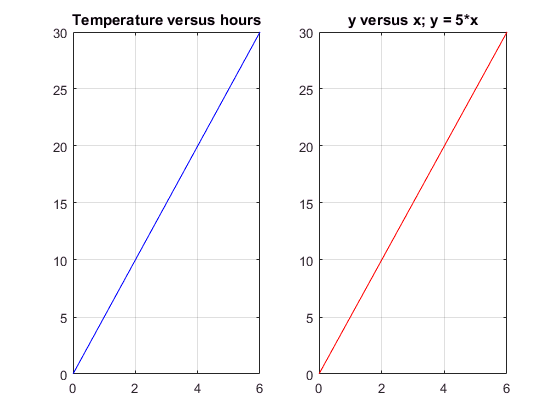

x = 0:6;
y = 5*x;
figure;

subplot(1,2,1)
plot(hours, temperature, 'b')
grid on
hold on
title('Temperature versus hours')
subplot(1,2,2)
plot(x, y, 'r')
grid on
title('y versus x; y = 5*x')

## Worksheet 1

x = 1:10;
y = x.^2;
px = [3,10]

px =      3    10


py = [0,84]

py =      0    84


lx = [6,6]

lx =      6     6


ly = [0,36]

ly =      0    36


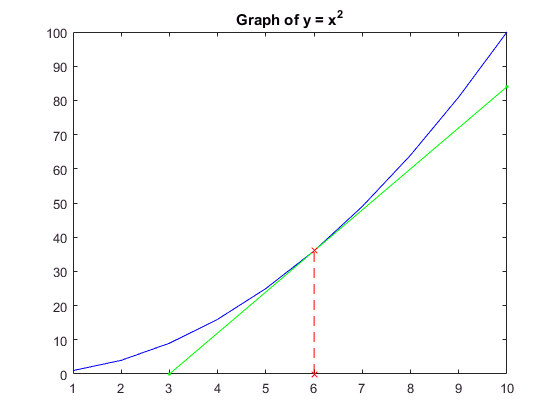

subplot(1,1,1)
grid on
plot(x,y, 'b')
hold on
plot(px,py, '.-g')
hold on
plot(lx, ly, '--xr')
title('Graph of y = x^2')

## Slope at x = 6, for y = x^2

slope = (36-0)/(6-3)

slope = 12

Note that slope of 12 = 2*6; thus at x = 6 the slope is 12 or twice the value of x

In our atempt above, we probably got lucky that we have found a line that is a tangent to the curve at the point x = 6. One way to proceed, when we get out of luck, is to to try with series of points close to x = 6. For example;

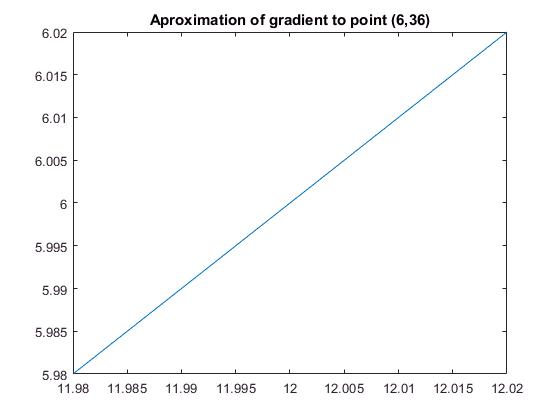

x = [5.98, 5.99, 5.995, 5.999, 6.001, 6.005, 6.01, 6.02];
y = x.^2;
deltax = x-6;
deltay = y-36;   % note that when x = 6 -> y = 6x6 = 36

gradient = deltay./deltax; % Note these are approximations of the gradient at x = 6
plot(gradient, x)
hold off
title('Aproximation of gradient to point (6,36)')

gradient

gradient =    11.9800   11.9900   11.9950   11.9990   12.0010   12.0050   12.0100   12.0200


 Note the gradient at point (6,36) is roughly twice the value of ordinate x (12 = 2*6)

## Using algebra

The gradient of chord AB is given by 'increase of y' / 'increase of x'. So, let's denote the 'increase of x' by dx and the 'increase of y' by dy. We will use the gradient as variable g

syms x dx
inc_of_x = (x+dx) - x;
inc_of_y = simplify((x+dx)^2 - x^2);
g = inc_of_y/inc_of_x

$$g = \mathrm{dx}+2\,x$$

Let's compute the limit of gradient g when dx approaches zero;

limit(g, dx, 0)

$$ans = 2\,x$$

It is the limit of the gradient expresion what is of interest. From now on, this is what we seek to find.

This procedure is referred to as 'differentiating from first principles' (according to the recommended textbook). Let's try it again with the expression:$x^3 + 5$

inc_of_y = simplify( expand( (x+dx)^3 + 5) - (x^3 + 5) )

$$inc\_of\_y = \mathrm{dx}\,\left({\mathrm{dx}}^{2}+3\,\mathrm{dx}\,x+3\,x^{2}\right)$$

inc_of_x = (x+dx) - x;
g = inc_of_y/inc_of_x

$$g = {\mathrm{dx}}^{2}+3\,\mathrm{dx}\,x+3\,x^{2}$$

limit(g, dx, 0)

$$ans = 3\,x^{2}$$

Finding the gradient at the point (2, 13) on the curve, x = 2. Notice the limit of the gradient for the curve $x^3 + 5$ gives the expression $3x^2$, and so at x = 2 the gradient is 3(2^2) = 12. 

It happens that Matlab can also perform the differentiation, it is performed in this way:

f1 = x^2;
df1 = diff(f1, x)

$$df1 = 2\,x$$

f2 = x^3 + 5;
df2 = diff(f2, x)

$$df2 = 3\,x^{2}$$

## Further exercises

By differentiating from first principles, find the derivative of:

a) $x-1$ and the gradient of the curve at point (3, 2)

b) $x^2 - x$ and the gradient of the curve at point (1, 0)

Solution to a)

inc_of_y = simplify( (x+dx) - 1 - (x -1) );
inc_of_x = (x + dx) - x;
g = inc_of_y/inc_of_x;
sol_a = limit(g, dx, 0)

$$sol\_a = 1$$

% Gradient at point (3, 2), x = 3, but gradient does not depend on x, so
% gradient at point (3, 2) is 1.
% checking with Matlab
dfa = diff(x-1, x)

$$dfa = 1$$

isequal(sol_a, dfa)

ans =      1


Solution to b)

inc_of_y = simplify( expand((x+dx)^2-(x+dx)) - expand(x^2 - x) )

$$inc\_of\_y = \mathrm{dx}\,\left(\mathrm{dx}+2\,x-1\right)$$

inc_of_x = (x + dx) - x;
g = inc_of_y/inc_of_x;
sol_b = limit(g, dx, 0)

$$sol\_b = 2\,x-1$$

% Gradient at point (1, 0); x = 1, so gradient is 2*1 - 1 = 1.
% Checking derivative with Matlab
dfb = diff(x^2-x, x)

$$dfb = 2\,x-1$$

isequal(sol_b, dfb) 

ans =      1
